# Heron's Shortest Path: Introduction to Optimization

Simple path planning example to illustrate formulating a problem for optimization.

The approach is similar to what we saw with solving ODEs

- Formulate the problem as an optimization problem (standard mathematical forms)

- Choose an appropriate algorithm (solver)

- Implement (code)

- Verify and validate solution (visualize and error management)

## Find the shortest path

(Adapted from ME3420, S. Kragelund)

Consider two villiages located along a river with the geometry shown below.  Village B is dealing with a tremendous fire.  The residents from village A wish to hlep and are seeking the shortest distance to B via the river $(r_A + r_B)$ so they can fill their buckets along the way.

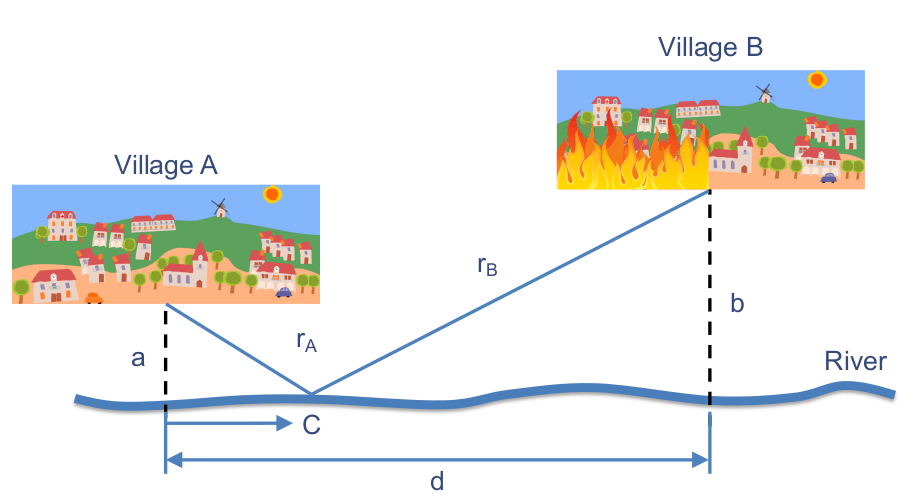

Specific parameters

Find the shortest route for our hasty villiagers?

## Approach

We could find a shortest (or at least a short) path a few ways: exaustive search, calculus (analytical solution) or optimization.

## Formulate as an optimzation problem

Optimization solvers can provide powerful algorithms for finding the "best" possible solution, but we need to define clearly what we mean by "best".  In this context we want to find the shortest path.  In terms of optimation, the *cost function* or *objective function* is the path length (distance), and we want to find the minimium. We can write an expression for the distance (path length) as a function of the distance along the river, $C$, as

$dist(C) = r_A + r_B = \sqrt{a^2 + C^2} + \sqrt{b^2 + (d-C)^2}$.

The "best" solution is a scalar value $C$ that minimizesOptimization solvers can provide powerful algorithms for finding the "best" possible solution, but we need to define clearly what we mean by "best".  In this context we want to find the value for $C$ that minimzes the cost function $dist(C)$,


$$\min_{C \in  	\mathbb{R}}  \left( \sqrt{a^2 + C^2} + \sqrt{b^2 + (d-C)^2} \right)$$


The optimal solution $C^* $ such which is the path that is shorter than all the other paths, that is

$dist(C^*) \leq dist(C)$.

General form:

decision variables: $\mathbf{x}$

scalar cost (objective) funtion: $f(\mathbf{x})$

optimization  $\min_{\mathbf{x} \in \mathbb{R}^n} f (\mathbf{x})$

optimal solutions: $f(\mathbf{x}^*) \leq f(\mathbf{x})$

C0 = 1;
[C, min_dist] = fminsearch(@cost_func, C0)

C = 2.0000

min_dist = 7.0711

Cost function

function dist = cost_func(C)
    % Specific parameters - distances in km
    a = 2;
    b = 3;
    d = 5;
    % Geometry
    rA = sqrt(a^2 + C.^2);
    rB = sqrt(b^2 + (d-C).^2);
    dist = rA + rB;
end

## Verify and Validate

Types of optimization

- constrained, unconstained

Types of solvers

- derivative free o